clear all; close all;
syms x1(t)
syms x2(t)
x = sym('x',[1 2]);


%================================>>>USER_INPUTS<<<============================
system42_syms = [   -x1+x2+x1^3; -x1]

$$system42\_syms(t) = \left(\begin{array}{c} {x_{1}\left(t\right)}^{3}-x_{1}\left(t\right)+x_{2}\left(t\right)\\ -x_{1}\left(t\right) \end{array}\right)$$


%Test compare to prev
%system42_syms = [   -x1+2*x1^2*x2; -x2]
%V = x1.^2/2+x2.^2
V = 0.5*(x1^2 + x2^2)

$$V(t) = \frac{{x_{1}\left(t\right)}^{2}}{2}+\frac{{x_{2}\left(t\right)}^{2}}{2}$$

l = 0.5;



% FUNNY math on analityc
V_prim = diff(V,t);
oldq = [diff(x1(t), t)', diff(x2(t), t)'];
V_prim = subs(V_prim, oldq', system42_syms);
V_prim_pureX = subs(V_prim, [x1, x2], x)

$$V\_prim\_pureX(t) = x_{1}\,\left({x_{1}}^{3}-x_{1}+x_{2}\right)-x_{1}\,x_{2}$$

%------------------------------------------->>>MATLAB CANT SOLVE ANALYTIC
%BOUNARY LINE <<<-------------------------------------

%matlab functions
system42_mf = matlabFunction(subs(system42_syms, [x1, x2], x));
V_mf = matlabFunction(subs(V, [x1, x2], x));
V_prim_mf = matlabFunction(subs(V_prim, [x1, x2], x));

%wrappers
system42 = @(t, x) system42_mf(t, x(1), x(2));
V_fun = @(x1, x2) V_mf(0, x1, x2);
V_prim_fun = @(x1, x2) V_prim_mf(0, x1, x2);

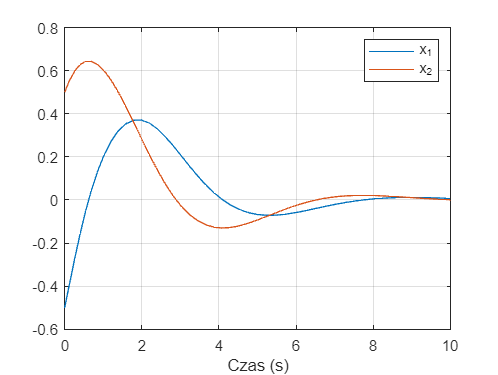

%Simulation
tmax = 100;
x0 = [-0.5, 0.5];
[t_resp,x_resp] = ode45(@(t,x) system42(t,x),[0 tmax],x0');
figure;
plot(t_resp, x_resp(:,1), t_resp, x_resp(:,2)), xlim([0 10]),
xlabel('Czas (s)'), legend('x_1','x_2'), grid on

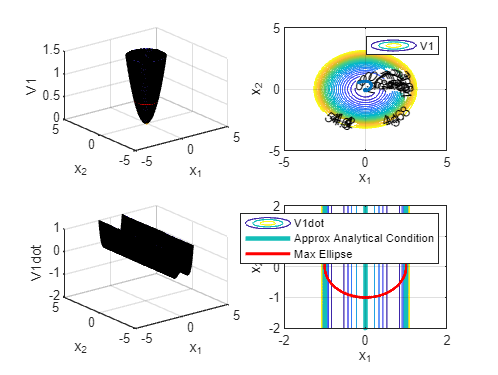

%calculate lasalle bound
lasalle_bound = solve(subs(V - l, [x1, x2], [x(1), x(2)]), x(1));
lasalle_bound_fun = matlabFunction(lasalle_bound);
x2_num = -5:0.001:5;
x1_num = lasalle_bound_fun(x2_num);
x1_num(x1_num~=real(x1_num)) = NaN;

% Analyze Lyapunov Functional and its derivative
% Set up a meshgrid
x1 = [-5:0.1:5];
x2 = [-5:0.1:5];
[X1,X2] = meshgrid(x1,x2);

figure;
subplot(2,2,1)
% Visualize Lyapunov functional as a surface
% Calcute functional over mesh
V1 = V_fun(X1, X2);
% Calculate functional for trajectory
V1_resp = V_fun(x_resp(:, 1), x_resp(:, 2));
surf(X1, X2, V1); hold all
% Visualize Lyapunov functional with value L
plot3(x1_num,x2_num,l*ones(length(x1_num),1),'r')
% Visualize value of Lyapunov functional along the example of trajectory 
plot3(x_resp(:,1),x_resp(:,2),V1_resp,'LineWidth',2)
xlabel('x_1')
ylabel('x_2')
zlabel('V1')
zlim([0 1.5]);

subplot(2,2,2)
% Visualize Lyapunov functional as a contour
[C,h] = contour(X1, X2, V1, [-5:0.2:5]);
clabel(C,h);
xlabel('x_1'), ylabel('x_2'), grid on, hold all
% Display trajectory traversing contours
plot(x_resp(:,1),x_resp(:,2),'LineWidth',2)
legend('V1')

subplot(2,2,3)
% Visualize derivative of Lyapunov functional along trajectories as surface
% Calcute derivative of Lyapunov functional over mesh
V1dot = V_prim_fun(X1, X2);
% Calculate derivative of Lyapunov functional for trajectory
V1dot_resp = x_resp(:,1).*(-x_resp(:,1)+2.*x_resp(:,1).^2.*x_resp(:,2))+2*x_resp(:,2).*(-x_resp(:,2));  
surf(X1, X2, V1dot);
xlabel('x_1'), ylabel('x_2'), zlabel('V1dot')
zlim([-2, 1])

subplot(2,2,4)
% Visualize derivative of Lyapunov functional along trajectories as contour
[C,h] = contour(X1, X2, V1dot,[-0.2:0.05:0.2]);
clabel(C,h), hold all;
contour(X1, X2, V1dot, [0,0], 'LineWidth', 3)
% Visualize approx analytical condition
% plot([-2:0.01:2],1./(2*[-2:0.01:2]),'LineWidth',2)


% Visualize ellipse
plot(x1_num,x2_num,'r','LineWidth',2)

xlim([-2 2]), ylim([-2 2]);
xlabel('x_1'), ylabel('x_2'), grid on
legend('V1dot','Approx Analytical Condition','Max Ellipse')

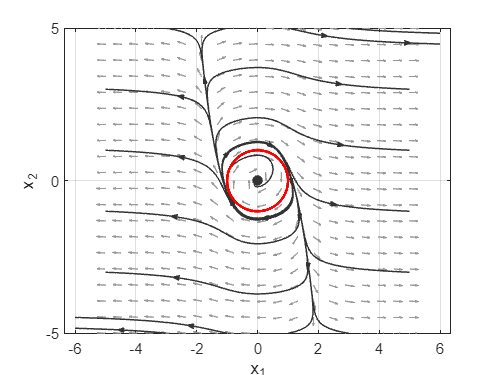

%Phase Portrait
figure
plotpp(@(t,x) system42(t,x), xlim = [-5, 5], ylim = [-5, 5]), hold all
xlabel('x_1'), ylabel('x_2')
xlim([-5 5]), ylim([-5 5])
axis equal

%Approx Analytical Condition
%plot([-5:0.1:5],1./(2*[-5:0.1:5]),'b','LineWidth',2)
%Select L for La Salle

%Plot ellipse as function of L
plot(x1_num, x2_num,'r', 'LineWidth', 2);


%% Select L maximising the ellipse as a region of attraction
%% Play with the figures and consider what you see:
% in particular derivative along trajectories
% what is the point of La Salle
% can we find a bigger region of attraction?